
$$\begin{array}{l}
f\left(x\right)=\frac{e^x -1-x}{x^2 }\\
T_5 f=\frac{1}{2}+\frac{1}{6}x+\frac{1}{24}x^2 \\
y\left(x\right)=\;\left\lbrace \begin{array}{ll}
T_5 f\left(x\right) & |x|\le \varepsilon \\
f\left(x\right) & \mathrm{altfel}
\end{array}\right.
\end{array}$$


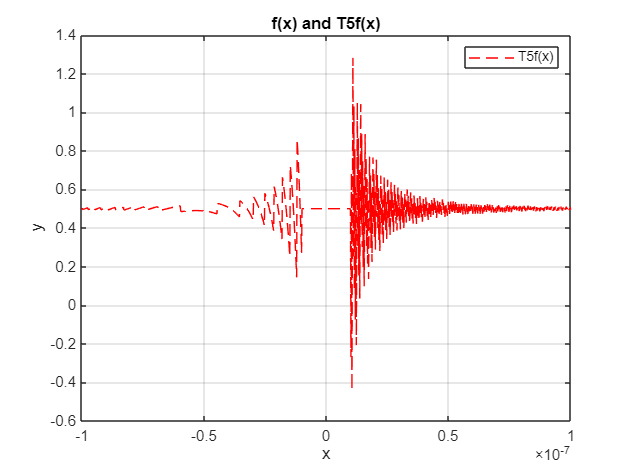

f = @(x) (exp(x) - 1 - x) ./ (x.^2);
T5f = @(x) 1/2 + (1/6)*x + (1/24)*x.^2;  % 5th degree expansion
epsilon = 10^-8;

f_aprox = @(x) (abs(x) < epsilon) .* T5f(x) + (abs(x) >= epsilon) .* f(x);

% Plot both functions and their relative difference
x = linspace(-10^(-7), 10^(-7), 1000);
y_f = f(x);
y_aprox = f_aprox(x);

figure;
%plot(x, y_f, 'b', 'DisplayName', 'f(x)');
%hold on;
plot(x, y_aprox, 'r--', 'DisplayName', 'T5f(x)');
title('f(x) and T5f(x)');
xlabel('x');
ylabel('y');
legend;  % This will display the legend
grid on

xlim("auto")
ylim("auto")